## Grobner Basis

Polynomial Division:

- Leading monomial: Monomial of the polynomial with the highest degree.

- Leading coefficient: Coefficient of the leading monomial.

- Leading term: Product of *a* and *b*.

- Degree of polynomial: Degree of the leading term.

- *Degree of remainder always lesser than that of the divisor.*

Monimial Orderings:

- Lexicographic ordering or Lex ordering: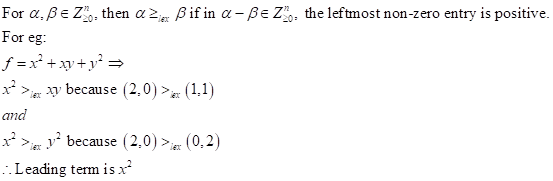

- Graded lexicographic ordering:

               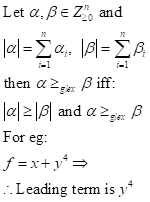

Multi-variate Polynomial Division:

- Dividing 2 polynomials:

              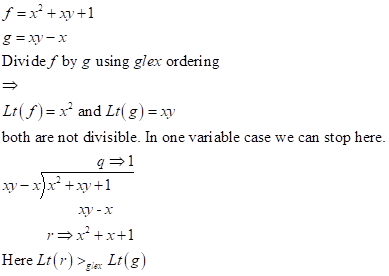

clear all;clc
syms x y
f = x^2+x*y+1;
d = x*y-x;
[r,q] = polynomialReduce(f,d)

$$r = x^{2}+x+1$$

$$q = 1$$

- Dividing by a system of polynomials: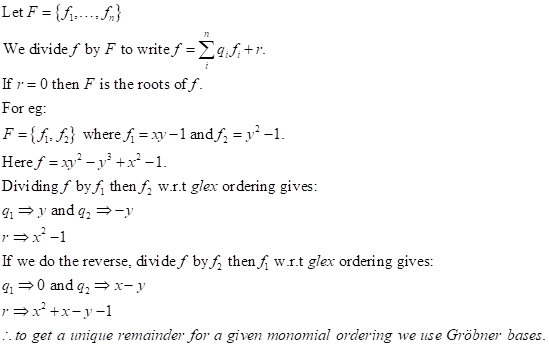

syms x y
f = x*y^2-y^3+x^2-1;
d1 = [x*y - 1, y^2 - 1];
d2 = [y^2 - 1, x*y - 1];
[r1,q1] = polynomialReduce(f,d1)

$$r1 = x^{2}-1$$

$$q1 = \left(\begin{array}{cc} y & -y \end{array}\right)$$

[r2,q2] = polynomialReduce(f,d2)

$$r2 = x^{2}+x-y-1$$

$$q2 = \left(\begin{array}{cc} x-y & 0 \end{array}\right)$$

Rings: A ring is a non-empty set equipped with 2 operations that satisfy the following axioms:

- It is closed under addition: $if \ a \in R \ and \ b \in R \ then \ a+b \in R$

- Associative

- Commutative

- Should have additive identity: $i.e \ 0_R \in a \ such\ that\ a+0_R=a=0_R+a \  \forall a \in R$

- Should have additive inverse.

- Closed under multiplication:$if\ a \in R\ and\ b\in R\ then\ a\bullet b \in R$

- Distributive and assosiative.

- *A set of ****Z****, ****Q**** and ****C**** are rings. Set of even numbers form a ring but set of odd nos don’t.*

Field:

- A subring *I* of a ring *R* is an **ideal** *iff *when* r **∈** R *and*a **∈ I, *then* r.a **∈** I *and *a.r **∈ I*. For eg. a set of even integers is an ideal of the ring ***Z*** and $\{0_R\}$ and ***R*** are ideals for every ring ***R***.

             

- The zero ideal is generated by a single element set; *I=<*$0_R$*>={*$0_R$*} **∀ *ring ***R***.

- Ideals can have different set of generators.

- Noetherian Rings: A ring ***R*** is a Noetherian ring if every ideal *I* of ***R*** is finitely generated. And, according to Hilbert’s Basis Theorem if *R* is a Noetherian ring then so is the polynomial ring *R[x]*.

Gröbner Basis: (LM(*f*) denotes fixed monomial ordering and LT(*f*) denotes the leading term.)

- A Gröbner basis of an ideal *I* is a set of generators of *I*.

- For a fixed monomial ordering a finite subset *G=*$\{g_1,...,g_t\}$ of an ideal *I* is said to be a Gröbner basis if:$<LT(g_1),...,LT(g_t)>=<LT(I)>$

- Reduced Gröbner basis: A RGb for a set of polynomials *F* is a Gröbner basis *G*of *F* such that: 1. LC is 1 $\forall p \in G$ and for all $p \in G$, none of the terms of *p* is divisible by the $LT(q) \ \forall \ q \in G-\{p\}$

- For a linear system of equations Grobner Basis is basically the Row Echelon form. For a univariate system of equations it is the GCD($f_1,...,f_m$). In general for an ideal **I **the Grobner basis consists of all the "smallest polynomials" in **I** for a given monomial ordering.

- S-polynomials: 

             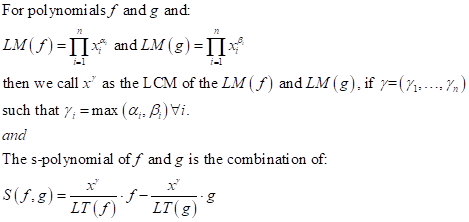

- For example:

             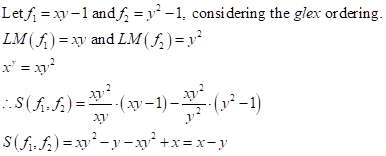

Buchberger's Algorithm:

- Chose the monomial ordering.

- Start with *G := F*.

- Repeat G’ := G until G = G’

              For example:

             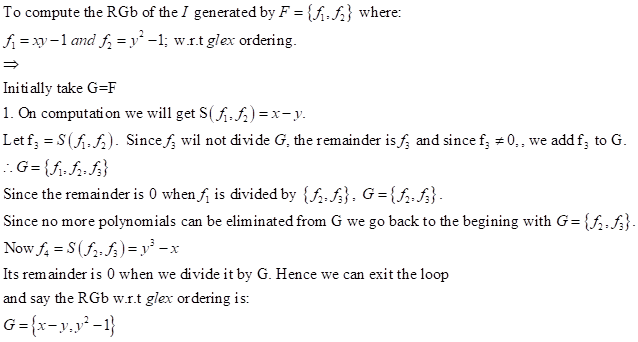

syms x y
r = [x*y-1, y^2-1];
G = gbasis(r)

$$G = \left(\begin{array}{cc} y^{2}-1 & x-y \end{array}\right)$$

Unique Remainders:

- For example:

            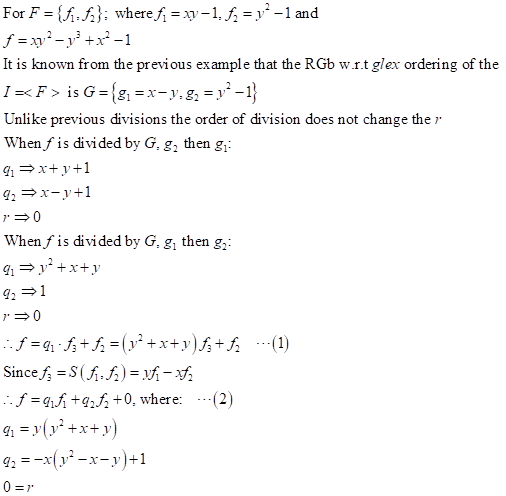

syms x y
f = x*y^2-y^3+x^2-1;
d = [x*y-1,y^2-1];
G = gbasis(d);
Gd = [G(1,2) G(1,1)];
[r1,q1] = polynomialReduce(f,G)

$$r1 = 0$$

$$q1 = \left(\begin{array}{cc} x-y+1 & x+y+1 \end{array}\right)$$

[r2,q2] = polynomialReduce(f,Gd)

$$r2 = 0$$

$$q2 = \left(\begin{array}{cc} y^{2}+y+x & 1 \end{array}\right)$$

        A zero remainder implies that the solutions of *F* are the roots of *f*. In conclusion, to divide a polynomial *f* by                  a set of polynomials *F* to get a unique remainder the following steps are to be followed:

- Compute Gröbner basis $G=\{g_1,...,g_t\}$ of the ideal *I=<F>.*

- Divide *f* by *G *to get a unique remainder *r*.

- Trace the quotients$q_i,\ i=1\ to\ n$ from the S-polynomials to write $f=q_1f_1+...+q_nf_n+r$

#### Inverse Kinematics Example

- Consider a robot with 2 revolute joints.     

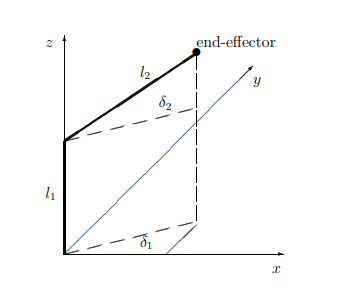

here we have 9 parameters; $l_1,l_2,p_x,p_y,p_z,\delta_1,\delta_2,s_1,s_2,c_1,c_2$ where $l_1,l_2$ are the link lengths; $p_x,p_y,p_z$ are the end-effector x-, y- and z- coordinates; $\delta_1, \delta_2$ are the angles describing the revolutions of the revolute joints; and $s_1,s_2,c_1,c_2$ are the sines and cosines of $\delta_1 \ and \ \delta_2$. 

        So with these we consider a system of equations:

given $l_1,l_2,p_x,p_z,$

solve for $s_1,s_2,c_1,c_2,p_y$

syms l1 l2 px pz s1 s2 c1 c2 py

Using these we can get 5 equations:


$$l_2.c_1.c_2-p_x=0,\\
l_2.s_1.c_2-p_y=0,\\
l_2.s_2 + l_1-p_z=0,\\
c_{1}^{2}+s_{1}^{2}-1=0\\
c_{2}^{2}+s_{2}^{2}-1=0$$


F = [l2*c1*c2 - px, l2*s1*c2-py, l2*s2+l1-pz, c1^2+s1^2-1, c2^2+s2^2-1];
G = gbasis(F,[c1 c2 s1 s2 py],'MonomialOrder','lexicographic');
siz = size(G);
for i=1:siz(2)
    disp(G(i))
end

$$c_{1}+\frac{\mathrm{px}\,\mathrm{py}\,s_{1}}{{l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}}$$

$$c_{2}+\frac{\mathrm{py}\,s_{1}\,\left(-{l_{1}}^{2}+2\,l_{1}\,\mathrm{pz}+{l_{2}}^{2}-{\mathrm{pz}}^{2}\right)}{l_{2}\,\left({l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}\right)}$$

$$\frac{{l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}}{-{l_{1}}^{2}+2\,l_{1}\,\mathrm{pz}+{l_{2}}^{2}-{\mathrm{pz}}^{2}}+{s_{1}}^{2}$$

$$s_{2}+\frac{l_{1}-\mathrm{pz}}{l_{2}}$$

$${l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}$$

These can be transformed into a Grobner Basis in the polynomial ring $\mathbb{Q}(l_1,l_2,p_x,p_z)[c_1,c_2,s_1,s_2,p_y]$:

This gives us 5 equations and 5 unknowns and thus solves the problem. Let:


$$l_1=30\\ l_2=45\\
p_x=\frac{45}{4}\sqrt{6}\\
p_z=\frac{45}{2}\sqrt{2}+30$$


L1 = 30;L2 = 45; PX = 45*sqrt(6)/4; PZ = 45*sqrt(2)/2+30;

subs1 = subs(G(5), [l1, l2, px, pz], [L1, L2, PX, PZ]);
sol1 = solve(subs1 , py,'ReturnConditions',true);
disp('py=')

py=


disp(vpa(sol1.py,6))

$$\left(\begin{array}{c} -15.9099\\ 15.9099 \end{array}\right)$$

siz = size(sol1.py);
if(siz(1) > 1)
    PY = vpa(sol1.py(2),6);
else
    PY = vpa(sol1.py,6);
end

Here we get py=$\left(\begin{array}{c}
-15.9099\\
15.9099
\end{array}\right)$. We take py=15.9099

subs2 = subs(G(4), [l1, l2, pz], [L1, L2, PZ]);
sol2 = solve(subs2 , s2,'ReturnConditions',true);
disp('s2=')

s2=


disp(vpa(sol2.s2,6))

$$0.707107$$

siz = size(sol2.s2);
if(siz(1) > 1)
    S2 = vpa(sol2.s2(2),6);
else
    S2 = vpa(sol2.s2,6);
end

s2=$0.707107$

subs3 = subs(G(3), [l1, l2, px, pz], [L1, L2, PX, PZ]);
sol3 = solve(subs3 , s1,'ReturnConditions',true);
disp('s1=')

s1=


disp(vpa(sol3.s1,6))

$$\left(\begin{array}{c} -0.5\\ 0.5 \end{array}\right)$$

siz = size(sol3.s1);
if(siz(1) > 1)
    S1 = vpa(sol3.s1(2),6);
else
    S1 = vpa(sol3.s1,6);
end

s1=$\left(\begin{array}{c}
-0.5\\
0.5
\end{array}\right)$. We take s1=0.5

subs4 = subs(G(2), [s1, l1, l2, px, py, pz], [S1, L1, L2, PX, PY, PZ]);
sol4 = solve(subs4 , c2,'ReturnConditions',true);
disp('c2=')

c2=


disp(vpa(sol4.c2,6))

$$0.707107$$

siz = size(sol4.c2);
if(siz(1) > 1)
    C2 = vpa(sol4.c2(2),6);
else
    C2 = vpa(sol4.c2,6);
end

c2=$0.707107$

subs5 = subs(G(1), [s1, l1, l2, px, py, pz], [S1, L1, L2, PX, PY, PZ]);
sol5 = solve(subs5 , c1,'ReturnConditions',true);
disp('c1=')

c1=


disp(vpa(sol5.c1,6))

$$0.866025$$

siz = size(sol5.c1);
if(siz(1) > 1)
    C1 = vpa(sol5.c1(2),6);
else
    C1 = vpa(sol5.c1,6);
end

and c1=$0.866025$

Thus the problem is solved with:


$$l_1=30;l_2=45,\\
p_x=\frac{45}{4}\sqrt{6}\\
p_z=\frac{45}{2}\sqrt{2}+30\\
and\ the\ solved\ variables\ are:\\
p_y=15.9099\\
s_2=0.707107\\
s_1=0.5\\
c_2=0.707107\\
c_1=0.866025$$


and the angles are:

del1 = vpa(rad2deg(acos(C1)),6);
del2 = vpa(rad2deg(acos(C2)),6);
disp('𝛿1=')

𝛿1=


disp(del1);

$$30.0$$

disp('𝛿2=')

𝛿2=


disp(del2);

$$45.0$$

- Now considering a 3-DOF 5R Robot.

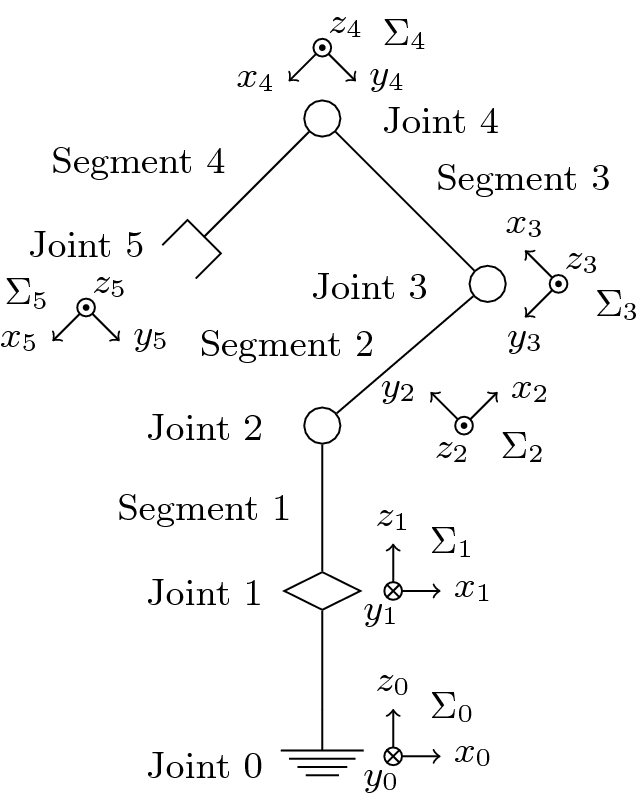

DH convention to express transformation from $(i-1)^{th}
$ system to $i^{th}$ system.


$$T^{i-1}_i = 
\pmatrix{
    1 & 0 & 0 & a_i 
\cr 0 & 1 & 0 & 0
\cr 0 & 0 & 1 & 0 
\cr 0 & 0 & 0 & 1}

\pmatrix{
    1 & 0 & 0 & 0
\cr 0 & cos(\alpha_i) & -sin(\alpha_i) & 0
\cr 0 & sin(\alpha_i) & cos(\alpha_i) & 0
\cr 0 & 0 & 0 & 1}

\pmatrix{
    1 & 0 & 0 & 0
\cr 0 & 1 & 0 & 0
\cr 0 & 0 & 1 & d_i
\cr 0 & 0 & 0 & 1}

\pmatrix{
 cos(\theta_i) & -sin(\theta_i) & 0 & 0
\cr sin(\theta_i) & cos(\theta_i) & 0 & 0
\cr    0 & 0 & 1 & 0
\cr 0 & 0 & 0 & 1}

\\
\ \ \ \  = \pmatrix{
 cos(\theta_i) & -sin(\theta_i) & 0 & a_i
\cr cos(\alpha_i)sin(\theta_i) & cos(\alpha_i)cos(\theta_i) & -sin(\alpha_i) & -d_i\ sin(\alpha_i)
\cr sin(\alpha_i)sin(\theta_i) & sin(\alpha_i)cos(\theta_i) & cos(\alpha_i) & d_i\ cos(\alpha_i)
\cr 0 & 0 & 0 & 1}$$


where $a_i$ is the distance beween $z_{
i-1}$ and $z_{i
}$, $\alpha_{
i}$ is the angle between axes $z_{
i-1}$ and $z_{i
}$ with respect to $x_{i
}$ axis, $d_{i
}$ is the distance between $x_{i-1
}$ and $x_{i
}$, and $\theta_{i
}$ the angle between axes $x_{i-1
}$ and $x_{i
}$ with respect to $z_{i
}$ axis.

Thus we can get $T_5^0 = T_1^0 T_2^1 T_3^2 T_4^3 T_5^4$ and the end effector position is the translation part of the matrix.


$$\pmatrix{x \cr y \cr z} = 

\pmatrix{t_{14} \cr t_{24} \cr t_{34}}$$


syms th1 th2 th3
the = [th1, pi/4, th2, th3, 0];
d = [8, 0, 0, 0, 0];
alp = [0, pi/2, 0, 0, 0];
a = [0, 0, 16, 16, 16];
T0_1 = getMat(a(1), alp(1),d(1),the(1));
T1_2 = getMat(a(2), alp(2),d(2),the(2));
T2_3 = getMat(a(3), alp(3),d(3),the(3));
T3_4 = getMat(a(4), alp(4),d(4),the(4));
T4_5 = getMat(a(5), alp(5),d(5),the(5));
T0_5 = T0_1*T1_2*T2_3*T3_4*T4_5;
simplify(T0_5)

x = 4;y = 9;z = 4;
EP = [x ; y ; z];

syms c1 s1 c2 s2 c3 s3
f1 = 8*sqrt(2)*c1*(c2+c3*(c2-s2)-s2-s3*(c2+s2)+1) - x;
f2 = 8*sqrt(2)*s1*(c2+c3*(c2-s2)-s2-s3*(c2+s2)+1) - y;
f3 = 8*sqrt(2)*(c2+c3*(c2+s2)+s2+s3*(c2-s2)+1) + 8 - z;
f4 = s1^2 + c1^2 - 1;
f5 = s2^2 + c2^2 - 1;
f6 = s3^2 + c3^2 - 1;

F = [f1,f2,f3,f4,f5,f6];
G = gbasis(F,[c1 c2 s1 s2 c3 s3],'MonomialOrder','lexicographic');
siz = size(G);
for i=1:siz(2)
    disp(G(i))
end

$$\begin{array}{l} \frac{4096\,{\left(4\,\sqrt{2}+1\right)}^{2}\,{\left(49\,\sqrt{2}+144\right)}^{2}\,{\left(4285056689609\,\sqrt{2}+6053188078404\right)}^{2}\,{\left(4300414836017897\,\sqrt{2}+6080032934632924\right)}^{3}\,{s_{3}}^{2}}{97\,\sigma_{1}\,\sigma_{2}}+c_{1}-\frac{4931998470683261107241950974268508356279796597531598442065080497168915794031125903367\,\sqrt{2}+6974899126843631473842051094371948341615147621508487708083436543486131946087599124980}{776\,\sigma_{1}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=36976968004953358887559416697497\,\sqrt{2}+52293327671145717866183178881656\\ \sigma_{2}=16691341836401860890223537885348028927955820983743\,\sqrt{2}+23605121998699167335451616314841660006056606393612 \end{array}$$

$$\begin{array}{l} \frac{9216\,{\left(4\,\sqrt{2}+1\right)}^{2}\,{\left(49\,\sqrt{2}+144\right)}^{2}\,{\left(4285056689609\,\sqrt{2}+6053188078404\right)}^{2}\,{\left(4300414836017897\,\sqrt{2}+6080032934632924\right)}^{3}\,{s_{3}}^{2}}{97\,\sigma_{1}\,\sigma_{2}}+s_{1}-\frac{9\,\left(4931998470683261107241950974268508356279796597531598442065080497168915794031125903367\,\sqrt{2}+6974899126843631473842051094371948341615147621508487708083436543486131946087599124980\right)}{3104\,\sigma_{1}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=36976968004953358887559416697497\,\sqrt{2}+52293327671145717866183178881656\\ \sigma_{2}=16691341836401860890223537885348028927955820983743\,\sqrt{2}+23605121998699167335451616314841660006056606393612 \end{array}$$

$$\begin{array}{l} -\frac{64\,\sqrt{2}\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,{\left(4300414836017897\,\sqrt{2}+6080032934632924\right)}^{2}\,{s_{3}}^{2}}{\sigma_{4}}+c_{3}+\frac{588580599471058615074607576662017317565252270487513059013823851822961\,\sqrt{2}+832378666321656889557724675469406070316325798780039063163321260054128}{512\,\sigma_{3}\,\sigma_{2}\,\sigma_{1}\,\sigma_{4}}\\ \mathrm{where}\\ \sigma_{1}=4285056689609\,\sqrt{2}+6053188078404\\ \sigma_{2}=49\,\sqrt{2}+144\\ \sigma_{3}=4\,\sqrt{2}+1\\ \sigma_{4}=16691341836401860890223537885348028927955820983743\,\sqrt{2}+23605121998699167335451616314841660006056606393612 \end{array}$$

function T = getMat(a, alp, d, the)
T = [cos(the), -sin(the), 0, a;
     cos(alp)*sin(the), cos(alp)*cos(the), -sin(alp), -d*sin(alp);
     sin(alp)*sin(the), sin(alp)*cos(the), cos(alp), d*cos(alp);
     0, 0, 0, 1];
end